mystartdefaults
step_size = 0.5;
x_min = -20;
x_max = 100;
x1_min = 0;
x1_max = 80;
n = (x_max - x_min)/step_size;
n1 = (x1_max - x1_min)/step_size;
tau = 1e-9;
gam = (hbar * 2 * pi/tau)/qel;
recipunit=1.0E+10;
ekinscale=(hbar * recipunit)^2/(2 * elm)/qel;

U_total = zeros(1,n); % Potential barriers
x = zeros(1,n);
for i = 1:n
    x(i) = x_min + step_size/2 + (i - 1) * step_size;
    if x(i) >= 0 && x(i) <= 15
        U_total(i) = 0.2;
    elseif x(i) >= 65 && x(i) <= 80
        U_total(i) = 0.2;
    else
        U_total(i) = 0;
    end
end
U = zeros(1,n1); % Potential barrier
x1 = zeros(1,n1);
for i = 1:n1
    x1(i) = x1_min + step_size/2 + (i - 1) * step_size;
    if x1(i) <= 15
        U(i) = 0.2;
    elseif x1(i) >= 65 && x1(i) <= 80
        U(i) = 0.2;
    else
        U(i) = 0;
    end
end
resoener=[0.01075,0.04325,0.09525,0.16325,0.07]; %Resonance energies found by looking at the R-T-A graph AND a non resonat enegry(the last one)
[~,n]=size(resoener);
wavefunctions=zeros(n,length(U_total));
W = zeros(length(U),length(U));

wavefunctions = zeros(n-1, length(U_total));
for i = 1:n
    k1 = sqrt((resoener(i) + 1i * gam)/ekinscale);
    for j = 1:length(U)
        phi0k(j) = exp(1i * k1 * x1(j));
        W(j,j) = step_size * U(j)/ekinscale;
        for k = 1:length(U)
            G0(j,k) = Greenf(0,x1(j),x1(k),resoener(i),gam,ekinscale);
        end
    end
    T = eye(length(U)) - G0 * W;
    phisol = T\(phi0k.');
    for j = 1:(length(U_total))
        if i < n
            wavefunctions(i,j) = exp(x(j) * 1i * k1) + outside_sol(x(j), x1, U, step_size, phisol, 0, resoener(i), gam, ekinscale);
        else
            nonresophi(j) = exp(x(j) * 1i * k1) + outside_sol(x(j),x1,U,step_size,phisol,0,resoener(i),gam,ekinscale);
        end
    end
end
resoprobas = abs(wavefunctions).^2;
nonresoproba = abs(nonresophi).^2;
for jj=1:length(U_total)    
  resoprobas(1,jj)= 0.0065*resoprobas(1,jj)+resoener(1);
  resoprobas(2,jj)= 0.002*resoprobas(2,jj)+resoener(2);
  resoprobas(3,jj)= 0.0005*resoprobas(3,jj)+resoener(3);
  resoprobas(4,jj)= 0.0027*resoprobas(4,jj)+resoener(4); 
  nonresoproba(jj)= 0.01*nonresoproba(jj)+resoener(n);
end

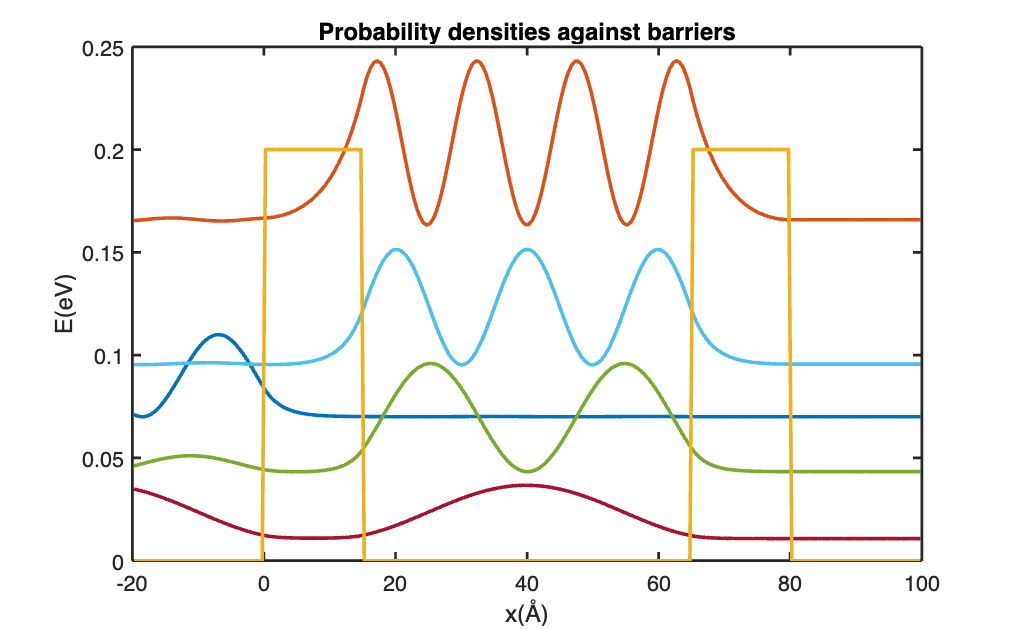

plot(x, nonresoproba, x,resoprobas, x, U_total, 'LineWidth',2);
title('Probability densities against barriers','FontSize',20);
ylim([0, 0.25]);
xlabel('x(Å)');
ylabel('E(eV)'); 
saveas(gcf, 'prob_density.png')

function [Gf]= Greenf(step,x,xp,E,gam,ekinscale) 
    ko=sqrt((E+1i*gam)/ekinscale);
    k1=sqrt((E+1i*gam-step)/ekinscale);
    if(x>=0 && xp>=0)
        Gf=exp(1i*k1*abs(x-xp))/(2i*k1) +  exp(1i*k1*(x+xp))*((k1-ko)/(k1+ko))/(2i*k1); % Green's function [A.76] for both positions greater than 0
    end

    if (x<0 && xp>=0)
        Gf=exp(-1i*ko*x+1i*k1*xp)/(1i*(ko+k1)); % Green's function [A.77] for x and xp  on different sides
    end
    if (xp<0 && x>=0)
        Gf=exp(-1i*ko*xp+1i*k1*x)/(1i*(ko+k1)); % Green's function [A.77] for xp and x  on different sides
    end
end
function[extra]= outside_sol(x,pos,V,dx,phisol,step,E,gam,ekinscale)
    extra=0;
    [~,n]=size(pos);
    for i = 1:n
        extra = extra + Greenf(step,x,pos(i),E,gam,ekinscale) * dx * (V(i)/ekinscale) * phisol(i); %equation [4.36]
    end
end